# CONTROL SYSTEMS PROJECT - ME23B201

## Physical Parameters

clear; clc; close all;

%% 1. PHYSICAL PARAMETERS (YOUR EXACT VALUES)
g = 9.81; % Acceleration due to gravity (m/s^2)

% Robot Body Parameters
M_r_kg = 11.1; % Mass of the robot body (kg)
d_mm = 198.05; % Distance from Axle to Center of Mass (mm)
h_mm = 328.05; % Height of the platform from Axle (mm)
R_mm = 328.00; % Radius of the robot wheels (mm)
M_w_kg = 4.4;  % Mass of one wheel (kg)

% Unit Conversions (mm to m)
d = d_mm / 1000;
h = h_mm / 1000;
R = R_mm / 1000;
M_r = M_r_kg;

% Ball Parameters
m_b_g = 2.71; % Mass of the ball (grams)
r_mm = 40.01; % Radius of the ball (mm)

% Unit Conversions
m_b = m_b_g / 1000; % Convert g to kg
r = r_mm / 1000;    % Convert mm to m
l = h + r;          % Effective lever arm (Axle to Ball Center)

% Moments of Inertia
I_b = (2/5) * m_b * r^2;                            % Ball (solid sphere)
I_r_com = (1/12) * M_r * (h^2 + d^2);              % Robot about CoM
I_r = I_r_com + M_r * d^2;                         % Robot about axle

fprintf('Parameters loaded successfully.\n');

Parameters loaded successfully.


fprintf('Robot Mass: %.2f kg | Ball Mass: %.4f kg\n', M_r, m_b);

Robot Mass: 11.10 kg | Ball Mass: 0.0027 kg


fprintf('l = %.4f m | I_r = %.4f kg·m² | I_b = %.6f kg·m²\n', l, I_r, I_b);

l = 0.3681 m | I_r = 0.5712 kg·m² | I_b = 0.000002 kg·m²


## Linearized Equations of Motion (Matrices M1, M2, M3)

% State Vector q = [x_ball; theta_robot]
% Equation: M1 * q_ddot = M2 * q + M3 * u

% Mass Matrix M1 
M1 = [(I_b/(r^2)) + m_b,  m_b*l;
      m_b*l,             I_r + m_b*(l^2)];

% M2 (Ballbot gravity - upright stable)
M2 = [0,              m_b*g;           % Ball horizontal coupling
      m_b*g, (M_r*d + m_b*l)*g];    % Robot restoring torque

% Input Matrix M3 
M3 = [-m_b*l;
      -(I_r + m_b*l^2)];
%M3 = [-m_b; -m_b*l]
fprintf('\nMatrices M1, M2, M3 generated .\n');


Matrices M1, M2, M3 generated .



%% 3. STATE-SPACE REPRESENTATION (A, B, C, D)
% State X = [x; x_dot; theta; theta_dot]
A_sub = M1 \ M2;  % inv(M1)*M2
B_sub = M1 \ M3;  % inv(M1)*M3

A = [0,     1,    0,    0;
     A_sub(1,1), 0, A_sub(1,2), 0;
     0,     0,    0,    1;
     A_sub(2,1), 0, A_sub(2,2), 0];

B = -[0;
      B_sub(1);
      0;
      B_sub(2)];

C = [0 0 1 0];  % Measure theta
D = 0;

## Controller Design (LQR) 

fprintf('State Space Model Generated.\n');

State Space Model Generated.


disp('A Matrix:'); disp(A);

A Matrix:
         0    1.0000         0         0
   -0.0122         0   -2.9180         0
         0         0         0    1.0000
    0.0465         0   37.7525         0



disp('B Matrix:'); disp(B);

B Matrix:
     0
     0
     0
     1




%% 4. SYSTEM ANALYSIS
poles = eig(A);
fprintf('\nOpen Loop Poles:\n'); disp(poles);


Open Loop Poles:
  -6.1440 + 0.0000i
   6.1440 + 0.0000i
   0.0000 + 0.0929i
   0.0000 - 0.0929i




if any(real(poles) > 0)
    fprintf('System Status: UNSTABLE (Controller required).\n');
else
    fprintf('System Status: STABLE.\n');
end

System Status: UNSTABLE (Controller required).



Co = ctrb(A,B);
if rank(Co) == 4
    fprintf('Controllability: FULLY CONTROLLABLE (Rank = 4).\n');
else
    fprintf('Controllability: NOT FULL (Rank = %d).\n', rank(Co));
end

Controllability: FULLY CONTROLLABLE (Rank = 4).



%% 5. REALISTIC LQR DESIGN (Bryson's Rule with YOUR safety limits)
x_limit = d/8;        % Ball position limit (±d/4)
theta_limit = deg2rad(15);  % 15° angle limit
xdot_max = 0.5;       % Reasonable velocity
thetadot_max = 2.0;   % Reasonable angular velocity
F_max = 5;           % Max wheel acceleration (m/s²)

% Bryson's Rule: Q_ii = 1/(max_state_i)^2
Q_lqr = diag([1/x_limit^2,  1/xdot_max^2,    1/theta_limit^2,  1/thetadot_max^2]);
R_lqr = 1/F_max^2;

fprintf('\n=== LQR WEIGHTS (Bryson''s Rule) ===\n');


=== LQR WEIGHTS (Bryson's Rule) ===


fprintf('Q = diag([%.1f, %.1f, %.1f, %.1f])\n', diag(Q_lqr));

Q = diag([1631.7, 4.0, 14.6, 0.2])


fprintf('R = %.4f\n', R_lqr);

R = 0.0400



%% 6. COMPUTE LQR GAIN
[K_lqr, S, poles_lqr] = lqr(A, B, Q_lqr, R_lqr);

fprintf('\n=== LQR RESULTS ===\n');


=== LQR RESULTS ===


fprintf('K_lqr = [%.3f, %.3f, %.3f, %.3f]\n', K_lqr);

K_lqr = [-201.427, -128.186, 155.885, 17.833]


fprintf('Closed-loop poles:\n'); disp(poles_lqr);

Closed-loop poles:
  -2.1909 + 2.8041i
  -2.1909 - 2.8041i
  -6.7257 + 1.1431i
  -6.7257 - 1.1431i




% Verify stability
A_cl = A - B*K_lqr;
if all(real(eig(A_cl)) < 0)
    fprintf('LQR: STABLE CLOSED-LOOP\n');
else
    fprintf('LQR: UNSTABLE\n');
end

LQR: STABLE CLOSED-LOOP



x_0 = [0.005, 0, deg2rad(2), 0]'

x_0 =     0.0050
         0
    0.0349
         0


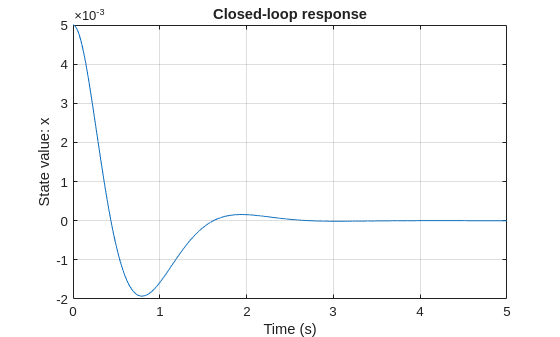


% Check settling time 
A_cl = A - B*K_lqr;
C_y  = [1 0 0 0];   % for x(t) settling time; change to [0 0 1 0] for theta
D_y  = 0;
sys_cl = ss(A_cl, B, C_y, D_y);
t = 0:0.001:5;           % 5 s sim, 1 ms step
x0 = x_0(:);             % your initial condition [0.005; 0; 2°; 0]

[y, t_out] = initial(sys_cl, x0, t);   % y is output (e.g., x(t))
info = lsiminfo(y, t_out);   % works for arbitrary response data

plot(t,y);
grid on;                        % turn grid on
xlabel('Time (s)');             % x-axis label
ylabel('State value: x');          % y-axis label
title('Closed-loop response'); 

Ts   = info.SettlingTime;
fprintf('Settling time: %.3f s\n', Ts);

Settling time: 5.000 s



lsiminfo(y, t)

ans = struct with fields:
    TransientTime: 2.2485
     SettlingTime: 4.9995
             Peak: 0.0050
         PeakTime: 0
              Min: -0.0019
          MinTime: 0.7950
              Max: 0.0050
          MaxTime: 0


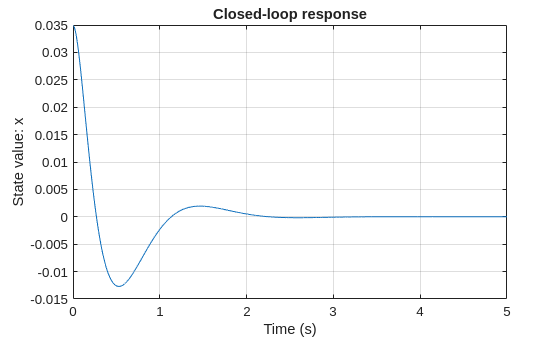


% Check settling time 
A_cl = A - B*K_lqr;
C_y  = [0 0 1 0];   % for x(t) settling time; change to [0 0 1 0] for theta
D_y  = 0;
sys_cl = ss(A_cl, B, C_y, D_y);
t = 0:0.001:5;           % 5 s sim, 1 ms step
x0 = x_0(:);             % your initial condition [0.005; 0; 2°; 0]

[y, t_out] = initial(sys_cl, x0, t);   % y is output (e.g., x(t))
info = lsiminfo(y, t_out);   % works for arbitrary response data

plot(t,y);
grid on;                        % turn grid on
xlabel('Time (s)');             % x-axis label
ylabel('State value: x');          % y-axis label
title('Closed-loop response'); 

Ts   = info.SettlingTime;
fprintf('Settling time: %.3f s\n', Ts);

Settling time: 4.988 s



lsiminfo(y, t)

ans = struct with fields:
    TransientTime: 1.9366
     SettlingTime: 4.9878
             Peak: 0.0349
         PeakTime: 0
              Min: -0.0127
          MinTime: 0.5290
              Max: 0.0349
          MaxTime: 0


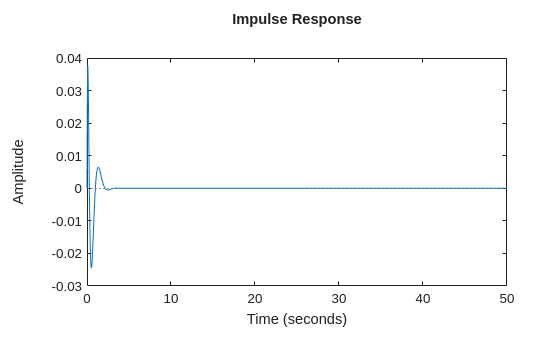


impulse(sys_cl,0:0.001:50)

## PID Controller

% Safety limits
x_limit = d/4;                 % ball can move only within +/- d/2
theta_limit = deg2rad(15);     % 15 degrees in radians

C_pid = eye(4)

C_pid =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


D_pid = zeros(4,1)

D_pid =      0
     0
     0
     0



[num,den] = ss2tf(A,B,C_pid,D_pid)

num =          0         0         0         0   -2.9180
         0         0         0   -2.9180         0
         0         0    1.0000         0    0.0122
         0    1.0000         0    0.0122         0


den =     1.0000   -0.0000  -37.7403    0.0000   -0.3261



function info = impulseinfo(t, y)
    % simplified impulse-response info
    % fields: Peak, SettlingTime, Overshoot

    y = y(:);
    t = t(:);

    % Peak
    [Peak, ~] = max(abs(y));

    % Final value
    final_val = y(end);

    % Overshoot (only meaningful if final != 0)
    if abs(final_val) > 1e-6
        Overshoot = (Peak - abs(final_val)) / abs(final_val);
    else
        Overshoot = NaN;   % consistent with control theory practice
    end

    % Settling time (2% band)
    err = abs(y - final_val);
    tol = 0.02 * abs(final_val);
    idx_set = find(err <= tol, 1, 'first');
    if ~isempty(idx_set)
        SettlingTime = t(idx_set);
    else
        SettlingTime = NaN;
    end

    info = struct('Peak', Peak, ...
                  'SettlingTime', SettlingTime, ...
                  'Overshoot', Overshoot);
end


s = tf('s');
G_theta = tf(num(3,:), den);
Kp_t = 3000; % Proportional gain
Ki_t = 10; % Integral gain
Kd_t = 25; % Derivative gain 25
C_theta = pid(Kp_t, Ki_t, Kd_t);
T_theta = feedback(C_theta*G_theta, 1);
pole(T_theta)

ans =  -12.4983 +52.9713i
 -12.4983 -52.9713i
  -0.0000 + 0.1108i
  -0.0000 - 0.1108i
  -0.0034 + 0.0000i


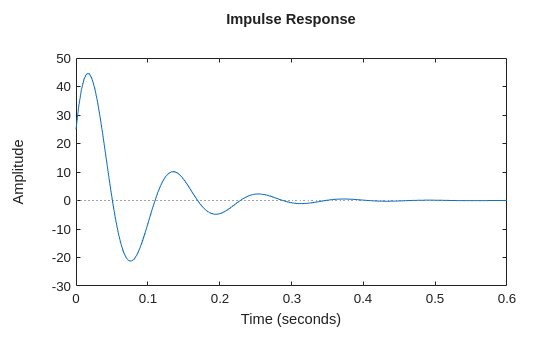

impulse(T_theta)


sys_pid = ss(A,B,C_pid,D_pid);     % 1 input (u), 4 outputs: [x; dx; θ; dθ]
C_theta = pid(Kp_t, Ki_t, Kd_t);   % tuned so θ response is fast & well damped
% inner_cl: input = θ_ref, outputs = [x; dx; θ; dθ]
inner_cl = feedback(sys_pid, C_theta, 1,3);

poles_inner = pole(inner_cl);
fprintf('Inner loop poles:\n');

Inner loop poles:


disp(poles_inner);

 -12.4983 +52.9713i
 -12.4983 -52.9713i
  -0.0000 + 0.1108i
  -0.0000 - 0.1108i
  -0.0034 + 0.0000i




% Check that all poles are in LHP (real part < 0)
if all(real(poles_inner) < 0)
    fprintf('Inner loop is STABLE ✓\n');
else
    fprintf('Inner loop is UNSTABLE ✗\n');
end

Inner loop is STABLE ✓


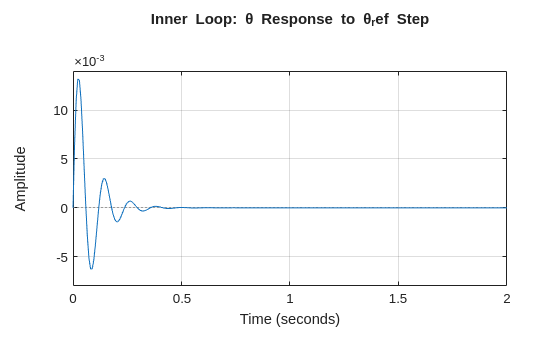



figure;
impulse(inner_cl(3,1), 2);  % θ (output 3) due to θ_ref (input 1)
title('Inner Loop: θ Response to θ_ref Step');
grid on;


% Get transfer function from θ_ref to x
Gx_outer = tf(inner_cl(1,1));  % x (output 1) / θ_ref (input 1)
Gx_outer = minreal(Gx_outer);  % clean up

fprintf('Outer loop plant (θ_ref → x):\n');

Outer loop plant (θ_ref → x):


disp(Gx_outer);

  tf with properties:

       Numerator: {[0 0 0 0 -2.9180 0]}
     Denominator: {[1 25.0000 2.9623e+03 10.3058 36.3745 0.1223]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]




% Check its poles
poles_outer = pole(Gx_outer);
fprintf('Outer plant poles:\n');

Outer plant poles:


disp(poles_outer);

 -12.4983 +52.9713i
 -12.4983 -52.9713i
  -0.0000 + 0.1108i
  -0.0000 - 0.1108i
  -0.0034 + 0.0000i



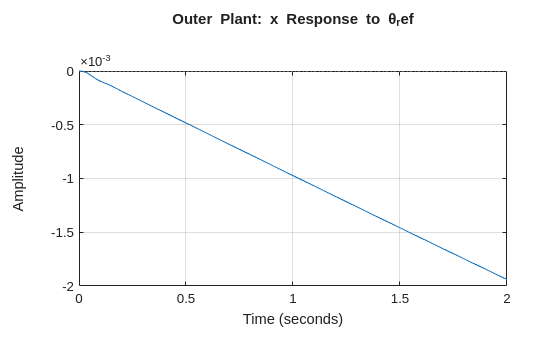


% Quick sanity check
figure; impulse(Gx_outer, 2);
title('Outer Plant: x Response to θ_ref');
grid on;

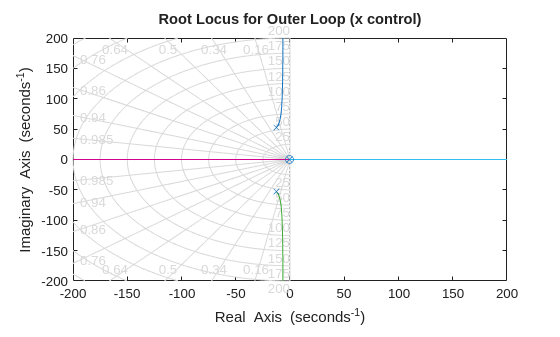


% Design outer controller
figure; rlocus(Gx_outer); grid on;
title('Root Locus for Outer Loop (x control)');

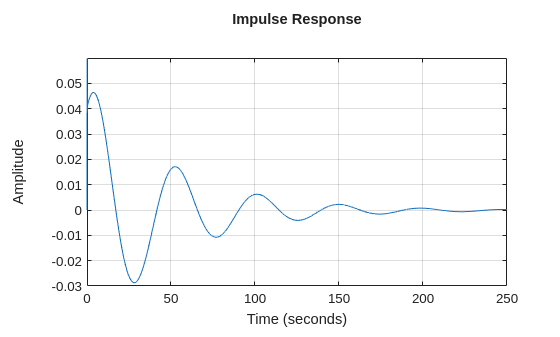



Kp_x = 5.0;
Ki_x = .01000;
Kd_x = 41;


C_x = pid(Kp_x, Ki_x, Kd_x);
T_x = feedback(-C_x*Gx_outer, 1);   % minus sign here

impulse(T_x); grid on;

pole(T_x)

ans =    0.0000 + 0.0000i
 -12.4781 +52.9665i
 -12.4781 -52.9665i
  -0.0204 + 0.1291i
  -0.0204 - 0.1291i
  -0.0030 + 0.0000i



% Combine both loops
C_x = -pid(Kp_x, Ki_x, Kd_x);  % your tuned outer controller
G_total = series(C_x, inner_cl);  % x_ref → θ_ref → [x;...]
T_total = feedback(G_total(1,1), 1);  % close outer feedback

% Simulate step response
figure; impulse(T_total, 700);
title('Complete Ballbot: x Response to x_ref');
grid on; hold on;
plot([0 5], [x_limit x_limit], 'r--', 'LineWidth', 1.5);
plot([0 5], [-x_limit -x_limit], 'r--', 'LineWidth', 1.5);
legend('Response', 'Safety Limit');
xlabel('Time (s)'); ylabel('Ball Position x (m)');

% Check performance
stepinfo(T_total)

ans = struct with fields:
         RiseTime: 3.4525
    TransientTime: 845.6607
     SettlingTime: 1.0494e+03
      SettlingMin: 0.1070
      SettlingMax: 0.5472
        Overshoot: 184.1253
       Undershoot: 0
             Peak: 0.5472
         PeakTime: 18.0845


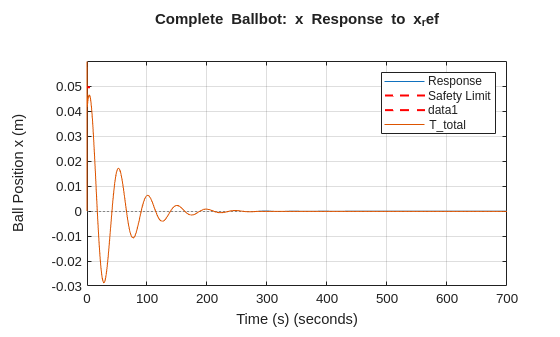

impulse(T_total)


[num_x, den_x] = tfdata(Gx_outer, 'v');

## Full state observer

%% --- Observability check ---
Ob = obsv(A, C);
fprintf('Observability rank = %d\n', rank(Ob));

Observability rank = 4



if rank(Ob) < size(A,1)
    warning('System is NOT fully observable with this C.');
else
    disp('System is fully observable with this C.');
end

System is fully observable with this C.



disp('--- Designing Full-State Observer (LQE) ---');

--- Designing Full-State Observer (LQE) ---



%% 1) Process noise covariance Q_est (for w_k)
% State vector: [x; x_dot; theta; theta_dot]
% Use Bryson-like scaling: Q_ii ≈ (max_model_error_i)^2
% Assume possible model errors (per time step) roughly:
x_err_max       = 0.002;     % 2 mm position model error
xdot_err_max    = 0.05;      % 0.05 m/s velocity model error
theta_err_max   = deg2rad(0.3); % 0.3 deg angle model error
thetadot_err_max= deg2rad(3);   % 3 deg/s angular rate model error

Q_est =100* diag([ ...
    x_err_max^2, ...
    ...
    xdot_err_max^2, ...
    ...
    theta_err_max^2, ...
    ...
    thetadot_err_max^2 ]);

%% 2) Noise input matrix G
% Assume process noise acts directly on each state derivative
G = eye(4);

%% 3) Measurement noise covariance R_est (for v_k)
% Suppose angle sensor has std ≈ 0.2 deg:
theta_meas_std = deg2rad(0.1);        % radians
R_est = theta_meas_std^2;            % scalar, since only 1 output

% No cross-correlation between process and measurement noise
N = zeros(4,1);

%% 4) LQE / continuous-time Kalman gain
[K_kalman, P_kalman, eig_observer] = lqe(A, G, C, Q_est, R_est, N);

disp('Observer gain K_kalman (L in observer equations):');

Observer gain K_kalman (L in observer equations):


disp(K_kalman);

   1.0e+03 *

    1.7119
    0.2121
    0.0400
    0.3505




disp('Observer poles (A - K_kalman*C):');

Observer poles (A - K_kalman*C):


disp(eig_observer);

  -0.1295 + 0.1702i
  -0.1295 - 0.1702i
 -10.2484 + 0.0000i
 -29.5038 + 0.0000i



## Min order observer

% Measured and unmeasured state indices
ia = [3];  % measured: theta, thetadot
ib = [1, 2, 4];  % unmeasured: x, xdot

% A partitions
A_aa = A(ia, ia);
A_ab = A(ia, ib);
A_ba = A(ib, ia);
A_bb = A(ib, ib);

% B partitions
B_a = B(ia);
B_b = B(ib);

% C partitions
C_a = C(:, ia);
C_b = C(:, ib);

% =========== DYNAMIC DIMENSIONING USING ia, ib ===========
na = length(ia);  % number of measured states
nb = length(ib);  % number of unmeasured states

% =========== DYNAMICALLY SIZED MATRICES ===========
G_min = 0.01 * eye(nb);    % nb × nb  process noise input
Q_min = 10000 * eye(nb);     % nb × nb  process noise covariance
Q_min(2,2) = 100

Q_min =        10000           0           0
           0         100           0
           0           0       10000


R_min = 0.05 * eye(na);   % na × na  measurement noise covariance
N_min = zeros(nb, na);     % nb × na  cross-covariance (typically zero)

[L_min, P_min, E_min] = lqe(A_bb, G_min, A_ab, Q_min, R_min, N_min);

% Minimum order observer Gain
Ke_min = L_min

Ke_min =     5.9995
    0.0659
    4.5341



A_obs = A_bb - Ke_min*A_ab;
B_obs = A_obs*Ke_min + A_ba - Ke_min*A_aa;
F_obs = B_b - Ke_min*B_a;
na = length(ia);   % measured states
nb = length(ib);   % unmeasured states

C_obs = zeros(4, nb);   % from observer state z to x_hat
C_obs(ib, :) = eye(nb);

D_obs = zeros(4, na);   % from measurement y to x_hat
D_obs(ia, :) = eye(na);

% Check observability
obs_rank = rank(obsv(A_bb, A_ab))

obs_rank = 3


x0_omin = [-0.02;0;0]

x0_omin =    -0.0200
         0
         0


## FFT

% y_noise  = out.y_noise.signals.values;
% ti = out.y_noise.time;
% save('noise_data.mat','y_noise','ti');

data = load('noise_data.mat')

data = struct with fields:
         ti: [100001×1 double]
    y_noise: [100001×1 double]


y_noise = data.y_noise;
ti      = data.ti;
Ts = ti(2) - ti(1)

Ts = 1.0000e-04

Fs = 1/Ts; 
N = length(y_noise);
Y = fft(y_noise - mean(y_noise));        
f = (0:N-1)*(Fs/N);          
P = abs(Y).^2 / N;           
figure; 
plot(f(1:N/2), P(1:N/2));

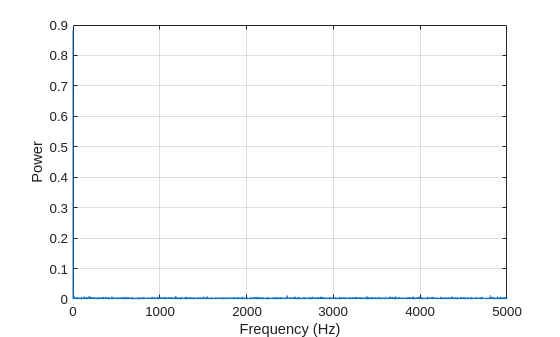

xlabel('Frequency (Hz)');
ylabel('Power');
grid on;

fc  = 20;        % cutoff
Fs  = 1/Ts;     % sample rate from your model
Wn  = fc/(Fs/2);
n   = 2;        % 2nd order

%butterworth filter
[b,a] = butter(n, Wn, 'low');